# 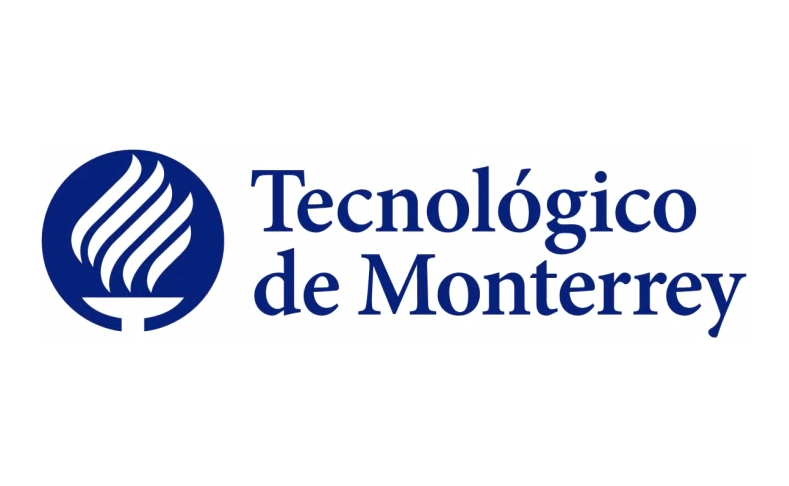 

# Simulación de la saponificación en reactores químicos utilizando equipo experimental didáctico 

Autor: Rodolfo Salazar Peña

Profesor Catedrático

Tecnológico de Monterrey - Campus Guadalajara

## Resumen

*Los reactores químicos constituyen el núcleo de los procesos de transformación de la materia, por lo que su estudio representa un eje fundamental en la formación de los ingenieros químicos. El sistema Pignat RAP/4000 integra cuatro tipos de reactores diseñados con fines didácticos, que permiten estudiar su dinámica y desempeño a escala de laboratorio. En este trabajo se presenta una herramienta interactiva de simulación de la reacción de saponificación en dichos reactores, y puede ser utilizada como complemento a la operación de este equipo. De esta manera, se pueden contrastar los modelos teóricos con la información experimental obtenida en el laboratorio.*

Palabras Clave: Pignat RAP/4000, Ingeniería Química, Reactores químicos, Modelado y Simulación, Educación en Ingeniería.

## Objetivos de Aprendizaje

- *Realizar un estudio comparativo de los cuatro tipos de reactores químicos disponibles en el sistema RAP/4000 (Cascada, CSTR, Serpentín, PFR y Lotes) identificando sus características de operación y desempeño en la reacción de saponificación, mediante simulación y análisis de datos experimentales, si se cuenta con estos últimos.*

- *Contrastar los resultados obtenidos por simulación de la reacción de saponificación con los datos experimentales generados en el laboratorio con el sistema RAP/4000, si se cuenta con estos.*

- *Analizar la influencia de las variables de proceso tales como las concentraciones iniciales de los reactivos y caudales de alimentación sobre la conversión y pureza del producto en la reacción de saponificación. Evaluar cómo estas variables determinan la calidad del producto obtenido y cómo ésto se puede aplicar en el desarrollo de nuevos productos químicos y biotecnológicos.*

## Antes de empezar 

Este cuaderno computacional en MATLAB, o Live Script está diseñado para usarse con el código visible y mostrando los resultados en el cuaderno. En la pestaña **View** de las opciones de MATLAB (Toolstrip), en la sección **View**, seleccione **Output Inline**. De forma alternativa, seleccione **Output inline **usando el ícono  en la esquina derecha del editor del Live Script. 

 Interactuar con este Live Script le permitirá familiarizarse con MATLAB a medida que se introducen conceptos y comandos juntos. Si necesita más entrenamiento, considere realizar el curso [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea de 2 horas que enseña los conceptos básicos de MATLAB. 

   Para una experiencia óptima, siga las instrucciones y pasos en la secuencia indicada. Pase a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se ejecutan en desorden.

En este cuaderno tendrá la oportunidad de explorar la visualización de conceptos introducidos, pero también podrá usar ejercicios que le permitirán interactuar con el código y desafiar su comprensión de esos conceptos y su profesor puede usarlas para calificar y verificar la finalización.

## Introducción

clear
clc

Los reactores químicos son fundamentales en la industria de la transformación de la materia. Si bien no todos los procesos de transformación requieren de reactores, estos no pueden ser prescindibles en la formación de ingenieros químicos. El sistema Pignat RAP/4000 consta de cuatro tipos reactores químicos con propósitos didácticos, estos son, (R2) Reactor Continuo de Tanque Agitado (CSTR), (R1) Sistema de dos CSTR en Cascada, (R3) Reactor tubular en serpentín y (R4) Reactor empacado en flujo tapón (PFR).

Este proyecto de simulación en MATLAB consta de dos archivos; el presente PignatRAP4000.mlx y RAP4000.slx que es el modelo de reactores R1 y R2 en Simulink, que es el núcleo de cómputo de la simulación para estos dos reactores. Se recomienda revisar este modelo, **pero de preferencia se recomienda mantenerlo cerrado mientras se manipulan los parámetros en la sección de Simulación R1 Y R2.**

openmodel=false;
if openmodel
    open("RAP4000.slx")
else
    close_system("RAP4000.slx",0)
end

En este recurso se presenta la simulación de la reacción de saponificación entre el Hidróxido de sodio (NaOH) y el Acetato de Etilo (EtOAc), dando como productos Acetato de Sodio (Ac) y Etanol (Et). La saponificación es el proceso de fabricación de jabones y detergentes, lo que constituye una gran importancia económica e industrial.

## Marco Teórico

### Cinética química

En la nomenclatura química tradicional reacción de saponificación se escribe de la siguiente manera: 


$$\mathrm{ \underset{(i\acute{o}n\,hidr\acute{o}xido)}{OH^-} +\underset{(acetato\,de\,etilo)}{CH_3COOCH_2CH_3} \to \underset{(i\acute{o}n\,acetato)}{CH_3COO^-} + \underset{(etanol)}{CH_3CH_2OH}}$$


En este trabajo se escribirá también se aceptará la siguiente forma simplificada:


$$\mathrm{ \underset{(Sosa)}{A} +\underset{(EtOAc)}{B} \to \underset{(Ac)}{C} + \underset{(Et)}{D}}$$


La cinética química para la saponificación es de segundo orden [1], esto es


$$r=\pm kC_\mathrm{A}C_\mathrm{B}$$


siendo *r* la tasa de generación (positivo) o consumo (negativo) en $\mathrm{M\,s^{-1}}$, *C* las concentraciones molares de los reactantes y *k* la constantes cinética de segundo orden en $\mathrm{M^{-1}\,s^{-1}}$.

Experimentalmente (ensayos previos) se ha determinado que

k=0.1078

k = 0.1078

Tanto en esayos por lotes o continuos las concentraciones de sosa y EtOAc pueden no ser necesariamente iguales (reactivo limitante y en exceso), pero si se comienzan con concentraciones cero para los productos, o no hay de estos en las alimentaciones, entonces por estequiometría se tiene que $C_\mathrm{C}=C_\mathrm{D}$. En este trabajo solamente se utilizará $C_\mathrm{D}$ para referirnos a las concentraciones molares de ambos productos, Ac y Et.

### Parámetros generales de los reactores

Los cuatro reactores del equipo Pignat RAP/4000 tienen en (L) un volumen total operativo de [2]

V=0.8

V = 0.8000

Los flujos volumétricos (caudales) en  de entrada a los sistemas reactivos están dados por $Q_\mathrm{A}$ para el hidróxido de sodio y $Q_\mathrm{B}$ para el EtOAc, siendo el caudal de salida $Q=Q_\mathrm{A}+Q_\mathrm{B}$.

### R2 CSTR Único

En el equipo Pignat RAP/4000 el segundo reactor es el CSTR único. Por ser más básico que el sistema en cascada, aquí se explicará éste primero.

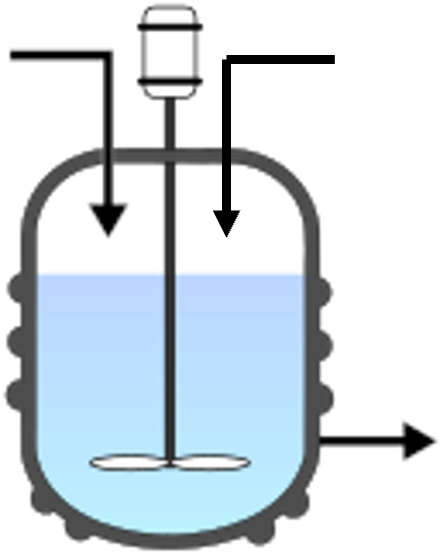

En R2 se alimentan ambos reactores. Imagen de reactor tomada de [3].

Las ecuaciones diferenciales gobernates de la dinámica del reactor son


$$ (\mathrm{R2}){\begin{cases}
\frac{\mathrm{d}C_\mathrm{A}}{\mathrm{d}t}=-kC_\mathrm{A}C_\mathrm{B}+\frac{Q_\mathrm{A}}{V}C_\mathrm{A,in}-\frac{Q}{V}C_\mathrm{A} &  C_\mathrm{A0}=0  \\
\frac{\mathrm{d}C_\mathrm{B}}{\mathrm{d}t}=-kC_\mathrm{A}C_\mathrm{B}+\frac{Q_\mathrm{B}}{V}C_\mathrm{B,in}-\frac{Q}{V}C_\mathrm{B} &  C_\mathrm{B0}=0 & \\
\frac{\mathrm{d}C_\mathrm{D}}{\mathrm{d}t}=kC_\mathrm{A}C_\mathrm{B}-\frac{Q}{V}C_\mathrm{D} &  C_\mathrm{D0}=0 & \\
\end{cases}$$


### R1 Dos CSTR en cascada

El sistema en cascada está formado por dos reactores CSTR cada uno de $V_1=0.4\,\mathrm{L}$.

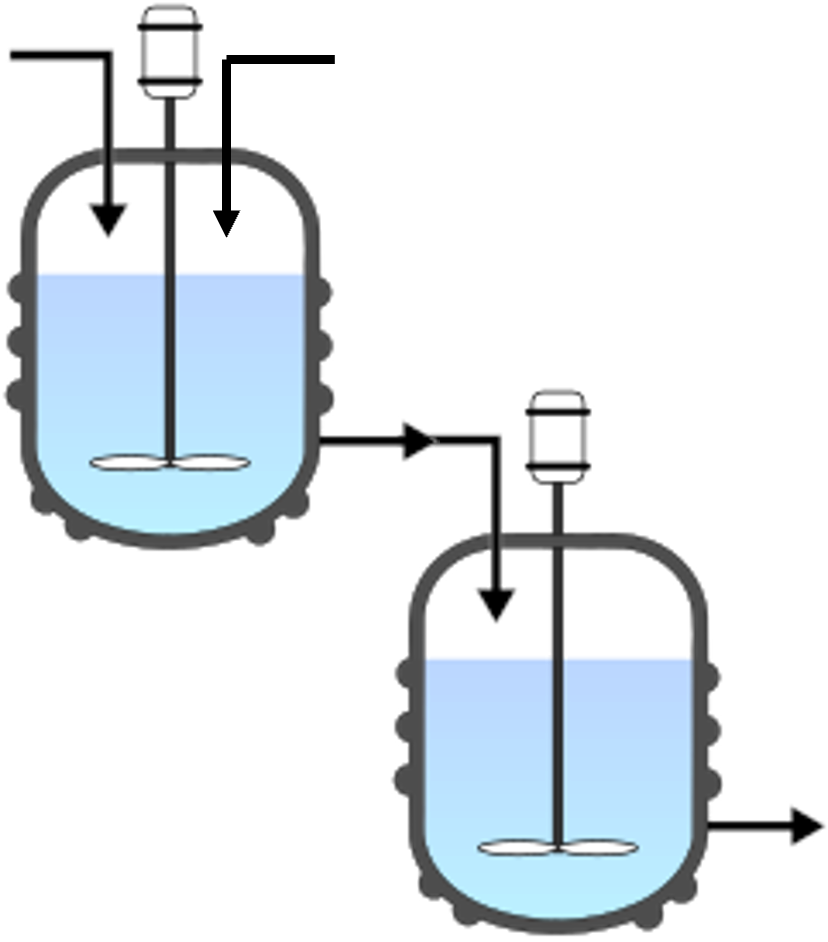

El reactor superior **R1a** está alimentado por A y B y el inferior **R1b** por el subproducto de **R1a**. La dinámica del sistema está regida por las ecuaciones


$$ (\mathrm{R1a}){\begin{cases}
\frac{\mathrm{d}C_\mathrm{A1}}{\mathrm{d}t}=-kC_\mathrm{A1}C_\mathrm{B1}+\frac{Q_\mathrm{A}}{V_1}C_\mathrm{A,in}-\frac{Q}{V_1}C_\mathrm{A1} &  C_\mathrm{A10}=0  \\
\frac{\mathrm{d}C_\mathrm{B1}}{\mathrm{d}t}=-kC_\mathrm{A1}C_\mathrm{B1}+\frac{Q_\mathrm{B}}{V_1}C_\mathrm{B,in}-\frac{Q}{V_1}C_\mathrm{B1} &  C_\mathrm{B10}=0 & \\
\frac{\mathrm{d}C_\mathrm{D1}}{\mathrm{d}t}=kC_\mathrm{A1}C_\mathrm{B1}-\frac{Q}{V_1}C_\mathrm{D1} &  C_\mathrm{D10}=0 & \\
\end{cases}\quad
 (\mathrm{R1b}){\begin{cases}
\frac{\mathrm{d}C_\mathrm{A}}{\mathrm{d}t}=-kC_\mathrm{A}C_\mathrm{B}+\frac{Q}{V_1}(C_\mathrm{A1}-C_\mathrm{A}) &  C_\mathrm{A}(\tau/2)=0  \\
\frac{\mathrm{d}C_\mathrm{B}}{\mathrm{d}t}=-kC_\mathrm{A}C_\mathrm{B}+\frac{Q}{V_1}(C_\mathrm{B1}-C_\mathrm{B}) &  C_\mathrm{B}(\tau/2)=0  & \\
\frac{\mathrm{d}C_\mathrm{D}}{\mathrm{d}t}=kC_\mathrm{A}C_\mathrm{B}+\frac{Q}{V_1}(C_\mathrm{D1}-C_\mathrm{D}) &  C_\mathrm{D}(\tau/2)=0 & \\
\end{cases}$$


obsérvese como el reactor R1b tiene un tiempo muerto aproximado de la mitad $\tau=V/Q$, que corresponde al tiempo de llenado de R1a.

### **R3 Reactor en serpentín**

Los R3 y R4 son tubulares y su concentración se estima en función de su recorrido, esto es, la distancia desde la alimentación hasta su salida. Para tal efecto es necesario aplicar un cambio de variable. Se tiene que la velocidad lineal promedio dentro de los reactores tubulares está dada por 

$v=\frac{Q}{A_T}=\frac{\mathrm{d}x}{\mathrm{d}t}$, 

luego se tiene que para cualquier concentración *C* 


$$\frac{\mathrm{d}C}{\mathrm{d}x}=\frac{\mathrm{d}t}{\mathrm{d}x}\frac{\mathrm{d}C}{\mathrm{d}t}=\frac{A_T}{Q}\frac{\mathrm{d}C}{\mathrm{d}t}$$


Entonces dinámica de los reactores tubulares está dada por las ecuaciones


$$ (\mathrm{R3}){\begin{cases}
\frac{\mathrm{d}C_\mathrm{A}}{\mathrm{d}x}=-\frac{A_T}{Q}kC_\mathrm{A}C_\mathrm{B} &  C_\mathrm{A0}=\frac{Q_\mathrm{A}}{Q}C_\mathrm{A,in}  \\
\frac{\mathrm{d}C_\mathrm{B}}{\mathrm{d}x}=-\frac{A_T}{Q}kC_\mathrm{A}C_\mathrm{B} &  C_\mathrm{B0}=\frac{Q_\mathrm{B}}{Q}C_\mathrm{B,in} & \\
\frac{\mathrm{d}C_\mathrm{D}}{\mathrm{d}x}=\frac{A_T}{Q}kC_\mathrm{A}C_\mathrm{B} &  C_\mathrm{D0}=0 \\
\end{cases}$$


siendo *x* la distancia o recorrido dentro del tubo. Las ecuaciones de R3 se resuelven en un dominio [0, L], siendo L la longitud total del reactor. R3 tiene un diámetro nominal (m)

Diametro=15e-3

Diametro = 0.0150

Luego, su área transversal es

AR3=pi*Diametro^2/4; % m^2

Siendo su volumen total en metros cúbicos

VT=V/1e3; %m^3

Por lo que su longitud total estimada en metros

LR3=VT/AR3

LR3 = 4.5271

### R4 reactor en flujo tapón

El último reactor es empacado por esferas de vidrio (canicas), tiene una longitud en metros de

LR4=1 

LR4 = 1

Se considera que el fabricante ha considerado un diámetro de tubo para llegar a los 0.8 L considerando el factor de empacamiento, por lo que se tiene que

AR4=VT/LR4

AR4 = 8.0000e-04

Esta área transversal no corresponde necesariamente a la auténtica del tubo. Se considera como el área promedio efectiva de flujo dado el empacamiento.

Se considera sin pérdida de generalidad que las ecuaciones para R3 son las mismas que para R4. Para los reactores tubulares se utiliza el solver [`ode45`](https://la.mathworks.com/help/matlab/ref/ode45.html) de MATLAB. Para tal efecto se programa una función del sistema de cuaciones diferenciales de R3 y R4.

function dCdx=odefcn(t,y,k,A,Qs)
dCdx=A*k*y(1)*y(2)*[-1; -1; 1]/Qs;
end

## Simulación R1 y R2

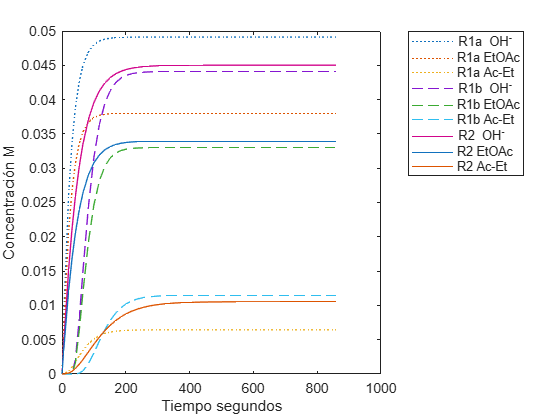

tspan=860;
QA=25;CAin=0.1;
QB=20;CBin=0.1;
simout=sim("RAP4000.slx");
t=simout.tout;
R1a=simout.xout{1}.Values.Data;
R1b=simout.xout{2}.Values.Data;
R2=simout.xout{4}.Values.Data;
plot(t,R1a,':',t,R1b,'--',t,R2)

legend('R1a OH^-','R1a EtOAc','R1a Ac-Et','R1b OH^-','R1b EtOAc','R1b Ac-Et','R2 OH^-','R2 EtOAc','R2 Ac-Et','Location','bestoutside')
xlabel('Tiempo segundos')
ylabel('Concentración M')

## Simulación R3 y R4

% Cálculos de condiciones inciales por mezclado en el punto inicial del reactor tubular (cero recorrido)

Q = 45

Q=QA+QB
Qs=Q/(1e3*3600);

CA0 = 0.0556

CA0=CAin*QA/Q

CB0 = 0.0444

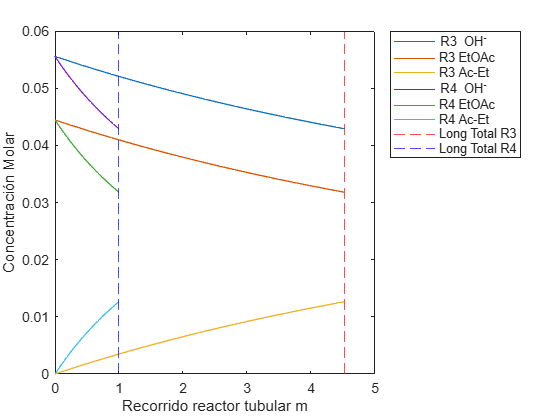

CB0=CBin*QB/Q
[recorrido3,R3]=ode45(@(t,y)odefcn(t,y,k,AR3,Qs),[0 LR3],[CA0; CB0; 0]);
[recorrido4,R4]=ode45(@(t,y)odefcn(t,y,k,AR4,Qs),[0 LR4],[CA0; CB0; 0]);
plot(recorrido3,R3,recorrido4,R4)
hold on
xline(LR3,'r--')
xline(LR4,'b--')
hold off
xlabel('Recorrido reactor tubular m')
ylabel('Concentración Molar')

legend('R3 OH^-','R3 EtOAc','R3 Ac-Et','R4 OH^-','R4 EtOAc','R4 Ac-Et','Long Total R3','Long Total R4','Location','bestoutside')

## Ejercicios adicionales 

- Genere un código que permita agregar una gráfica en la que se presente el desempeño de todos los reactores bajo las mismas condiciones de operación. ¿Qué reactores tienen mejor desempeño?

% Celda para adicionar código

        2. Juegue con las condiciones de operación para simular un ensayo por lotes (batch) en R2 de 0.4 L de NaOH 0.1 M y 0.3 L de EtOAc 0.1 M. ¿Es necesario acceder al modelo en Simulink? 

## Preguntas y ejercicios de reflexión y análisis

- De los reactores de CSTR único R1 y CSTRs en cascada R2, ¿Cuál tiene mejor desempeño y es significativa esta diferencia?

- De los reactores de CSTR único R1 y CSTRs en cascada R2, ¿El esquema que tenga mejor desempeño será siempre mejor? ¿Porqué sí o porque no podría suceder esto?

- De los reactores CSTR R1 y R2 vs., los reactores tubulares R3 y R4, ¿Qué esquema de reactores tendrán siempre mejor desempeño? ¿Porqué sí o porque no podría suceder esto?

- De los reactores tubulares R3 y R4, ¿tendrán siempre el mismo rendimiento o por lo menos cercano a pesar de tener longitudes diferentes? ¿Porqué podría estar sucediendo esto? 

- ¿Qué factores podrían hacer cambiar la constante cinética *k* de segundo orden? ¿Cómo podría incorporar estos cambios en este programa haciendo el cambio de manera interactiva?

- Tiene un suministro limitado de Acetato de Etilo y abundante de Hidróxido de Sodio por lo que puede tener soluciones diluidas del primero y fuertes del segundo, pero no desea que su producto final tenga un pH elevado, ¿cómo podría jugar con condiciones de operación para lograr este objetivo? Ilustre con simulaciones.

- Tiene un suministro abudante de Acetato de Etilo y limitado de Hidróxido de Sodio por lo que puede tener soluciones fuertes del primero y diluidas del segundo, pero no desea que su producto final tenga consistencia grasosa, ¿cómo podría jugar con condiciones de operación para lograr este objetivo? Ilustre con simulaciones.

## Referencias 

[1] Ira N. Levine. *Fisicoquímica*. 3.a ed. México, D.F.: McGraw-Hill, 1988.

[2] [RAP/4000](https://pignat.com/es/product-tag/rap-4000-es/).

[3] [Archivo:Continuous bach reactor CSTR.svg](https://es.wikipedia.org/wiki/Archivo:Continuous_bach_reactor_CSTR.svg) Dominio Público

### Bibliografía Adicional

- Robert Thornton Morrison y Robert Neilson Boyd. Química Orgánica. 5.a ed. Wilmington DE:Addison-Wesley Iberoamericana, 1987.

- L. G. Wade Jr. *Química Orgánica*. 2.a ed. Naucalpan de Juárez, Méx.: Prentice Hall, 1991.

- Salvat y Synopsis. Grasas y Detergentes. En: *Enciclopedia Salvat del Estudiante*. Salvat Mexicana de Ediciones, 1984.

- Kuang-Hui Lin. Cinética de las reacciones, diseño de reactores y termodinámica. En: *Biblioteca del Ingeniero Químico*. Ed. por Robert H. Perry y Cecil H. Chilton. 5.a ed. México, D.F.: McGraw-Hill, 1973. Cap. 4.

- H. Scott Fogler. *Elements of Chemical Reaction Engineering*. 2.a ed. Prentice Hall International Series in the Physicial and Chemical Engineering Series. Upper Sandler River NJ: Prentice Hall, 1992.

- J. M. Smith. *Chemical Engineering Kinetics*. 3.a ed. Chemical Engineering Series. Singapore: McGraw-Hill, 1981.

- Octave Levenspiel. *Ingeniería de las Reacciones Químicas*. 2.a ed. México, D.F.: Reverté, 1972.

- Ronald W. Missen, Charles A. Mims y Bradley A. Saville.* Introduction to Chemical Reaction Engineering and Kinetics*. New York NY: John Wiley & Sons, 1999.

- Lanny D. Schmidt. *The Engineering of Chemical Reactions*. Topics in Chemical Engineering. New York NY: Oxford University Press, 1998.

- Julio F. Mata-Segreda. Hydroxide as General Base in the Saponification of Ethyl Acetate. En: *J. Am. Chem. Soc.* 124.10 (2002), págs. 2252-2262. doi: [10.1021/ja011931t](https://pubs.acs.org/doi/10.1021/ja011931t).

- Kuheli Das et al. Kinetic Studies on Saponification of Ethyl Acetate Using an Innovative Conductivity-Monitoring Instrument with a Pulsating Sensor. En: International Journal of Chemical Kinetics (2011). doi: [10.1002/kin.20597](https://onlinelibrary.wiley.com/doi/abs/10.1002/kin.20597).